**Question Two: **Non-genericity of a pitchfork bifurcation


$$f_a \left(x\right)=x^3 -\mathrm{ax}+b$$


syms a b x;
f = x^3 -a*x

$$f = x^{3}-a\,x$$

fixedPoints = solve(f-x,x)

$$fixedPoints = \left(\begin{array}{c} 0\\ \sqrt{a+1}\\ -\sqrt{a+1} \end{array}\right)$$

**Part A: **Demonstrate that $f_a(x)$ undergoes a pitchfork bifurcation when $b=0$

**Solution: **

We proceed using the criteria established in Wiggins to show that  $f_a(x)$has a pitchfork bifurcation when b = 0:

- 
$$\frac{\partial f}{\partial a}\left(a,x\right)=0$$


- 
$$\frac{\partial f}{\partial x}\left(a,x\right)=1$$


- 
$$\frac{\partial^2 f}{\partial x^2 }\left(a,x\right)=0$$


- 
$$\frac{\partial^2 f}{\partial x\partial a}\left(a,x\right)\not= 0$$


- 
$$\frac{\partial^3 f}{\partial x^3 }\left(a,x\right)\not= 0$$


We begin by determining at what values of a condition 2 is verified:

pF_x = diff(f,x);

x = fixedPoints(1)

$$x = 0$$

pF_x1 = subs(pF_x)

$$pF\_x1 = -a$$

a1 = solve(pF_x1-1,a)

$$a1 = -1$$


x = fixedPoints(2)

$$x = \sqrt{a+1}$$

pF_x2 = subs(pF_x)

$$pF\_x2 = 2\,a+3$$

a2 = solve(pF_x2-1,a)

$$a2 = -1$$


x = fixedPoints(3)

$$x = -\sqrt{a+1}$$

pF_x3 = subs(pF_x)

$$pF\_x3 = 2\,a+3$$

a2 = solve(pF_x3-1,a)

$$a2 = -1$$

**Interpretation: ** Note that for all fixed points, $a_{1,2,3} =1$. Plugging in $a_2 ,a_3$ into $x_2 ,x_3$ respectively returns the same fixed point $x=0$. Thus, we expect the pitchfork bifurcation to happen at $\left(a,x\right)=\left(-1,0\right)\ldotp \;$

To confirm, we calculate the derivatives outlined by Wiggins and evaluate them at $\left(a,x\right)=\left(-1,0\right)\ldotp \;$

syms a x;
f = x^3 -a*x

$$f = x^{3}-a\,x$$


pF_x = diff(f,x)

$$pF\_x = 3\,x^{2}-a$$

pF_xx = diff(pF_x,x)

$$pF\_xx = 6\,x$$

pF_xxx = diff(pF_xx,x)

$$pF\_xxx = 6$$

pF_a = diff(f,a)

$$pF\_a = -x$$

pF_ax = diff(pF_a,x)

$$pF\_ax = -1$$

The calculation above returns:

- 
$$\frac{\partial f}{\partial a}\left(a,x\right)=-x$$


- 
$$\frac{\partial f}{\partial x}\left(a,x\right)=3x^2 -a$$


- 
$$\frac{\partial^2 f}{\partial x^2 }\left(a,x\right)=6x$$


- 
$$\frac{\partial^2 f}{\partial x\partial a}\left(a,x\right)=-1$$


- 
$$\frac{\partial^3 f}{\partial x^3 }\left(a,x\right)=-6$$


Substituting, we immeadiately note that:

- 
$$\frac{\partial f}{\partial a}\left(-1,0\right)=0$$
 

- 
$$\frac{\partial f}{\partial x}\left(-1,0\right)=1$$


- 
$$\frac{\partial^2 f}{\partial x^2 }\left(-1,0\right)=0$$


- 
$$\frac{\partial^2 f}{\partial x\partial a}\left(-1,0\right)=-1$$


- 
$$\frac{\partial^3 f}{\partial x^3 }\left(-1,0\right)\;=\;6$$


Thus all conditions for a pitchfork bifurcation are met. 

**Part B: **Identify what bifurcation gives rise to the birth of two fixed points when $b\not= 0$

Intuition (and the book) point to a saddle node bifurcation. To show this, consider the graph of $f_a \left(x\right)=x^3 -\mathrm{ax}+b$ when $a=-1,b=0$. 

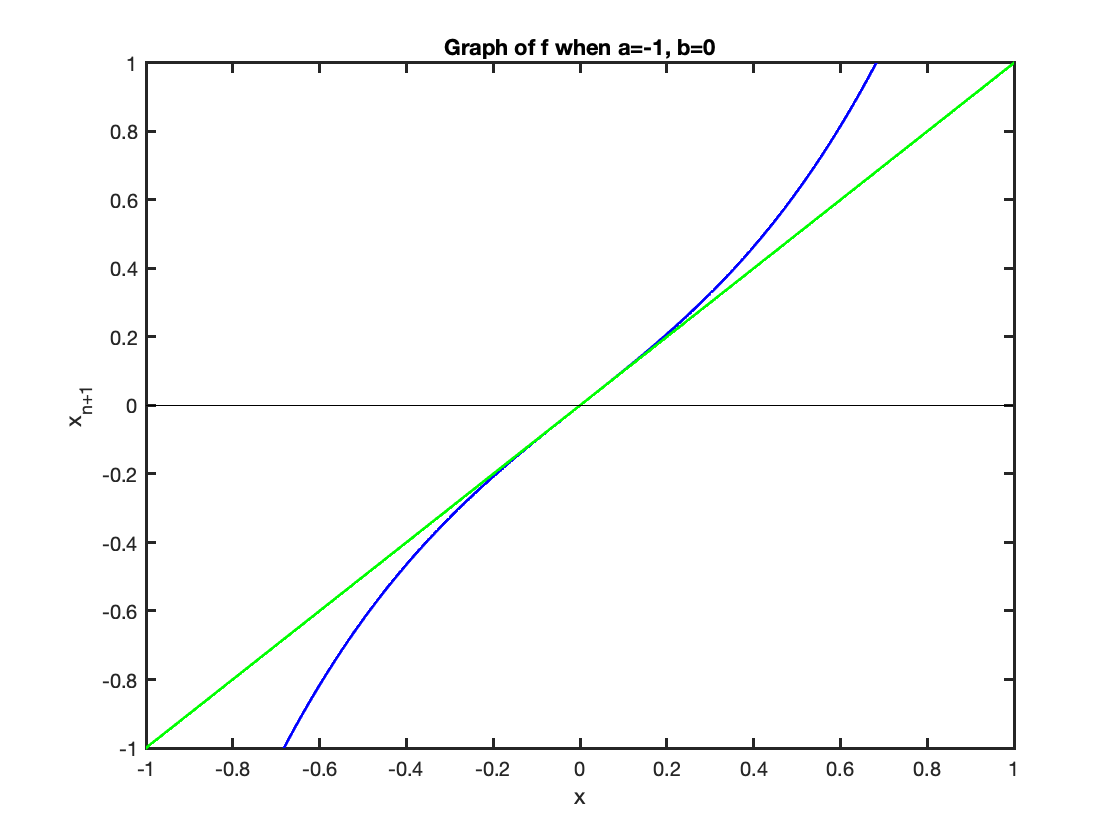

x=[-1:0.001:1];
y = x.^3 + x;
z=x;
w = x-x;
plot(x,y,'b','linewidth',1.5)
hold on
plot(x,z, 'g', 'linewidth',1.5)
plot(x, w, 'k')
set(gcf,'color','w');
set(gca,'linewidth',1.5)
ylim([-1 1])
xlabel('x');
ylabel('x_{n+1}');
title('Graph of f when a=-1, b=0');
hold off

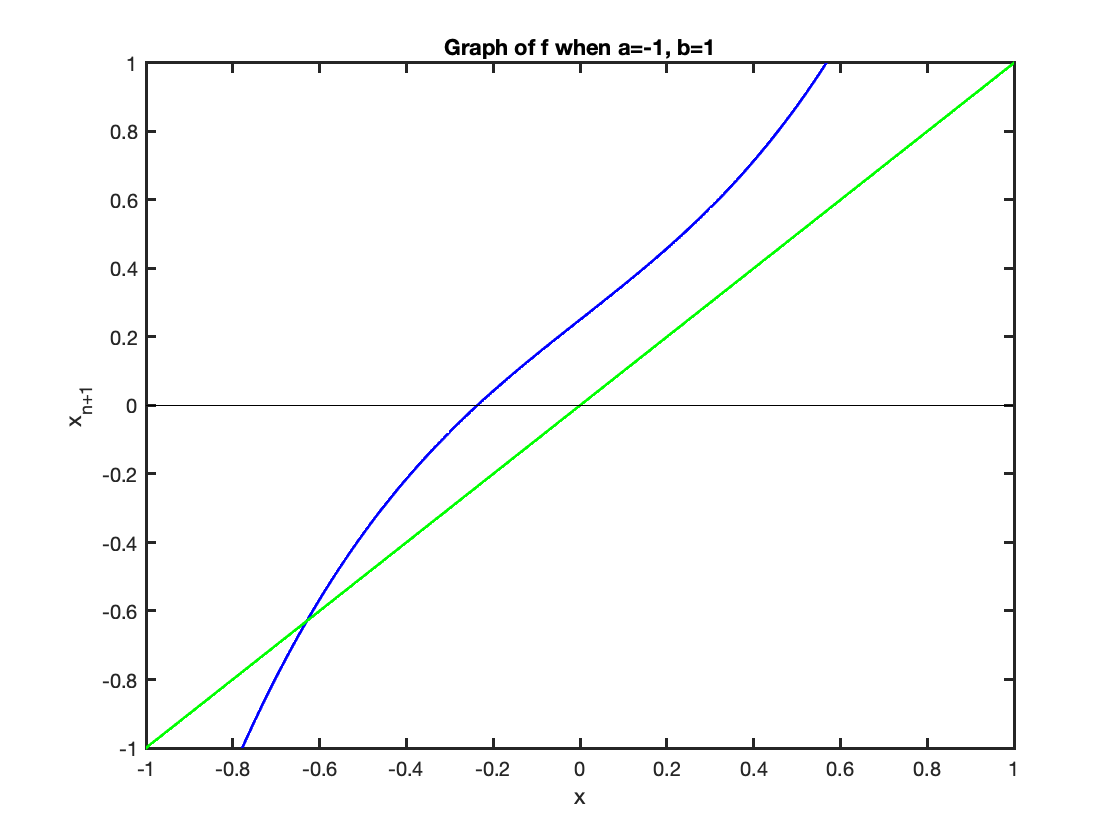


y = x.^3 + x +0.25;
plot(x,y,'b','linewidth',1.5)
hold on
plot(x,z, 'g', 'linewidth',1.5)
plot(x, w, 'k')
set(gcf,'color','w');
set(gca,'linewidth',1.5)
ylim([-1 1])
xlabel('x');
ylabel('x_{n+1}');
title('Graph of f when a=-1, b=1');
hold off

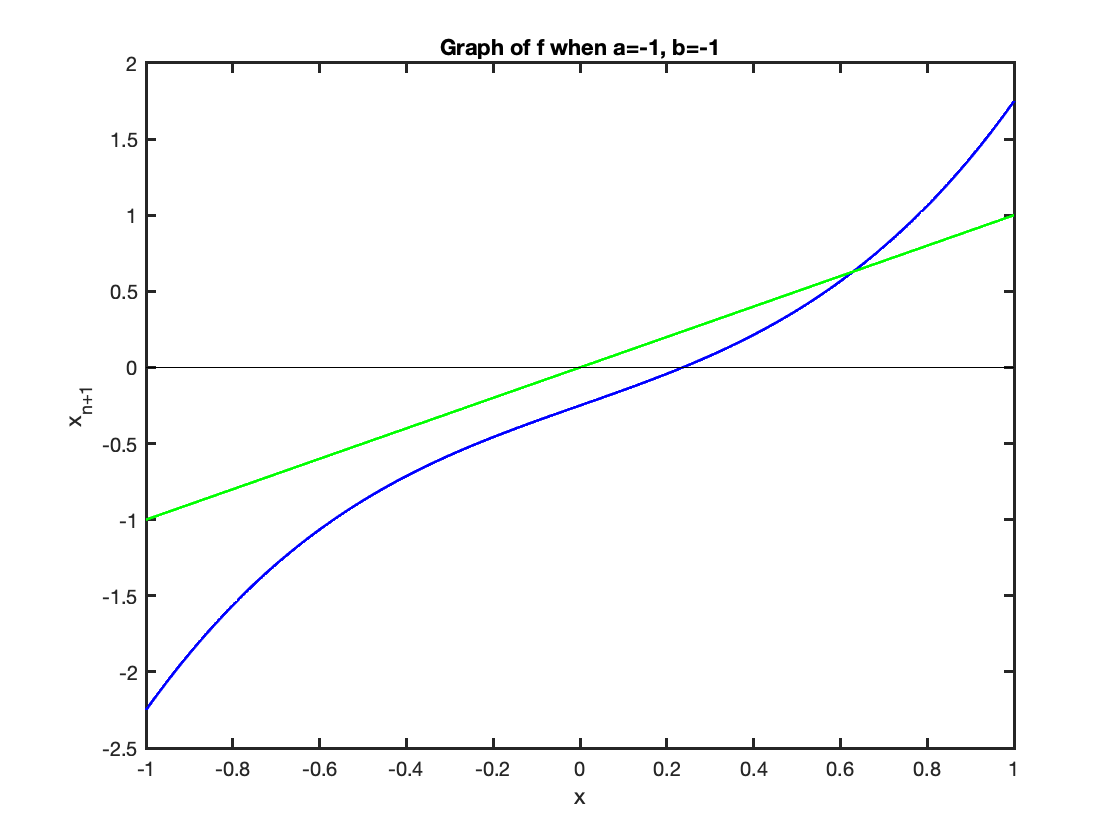


y = x.^3 + x -0.25;
plot(x,y,'b','linewidth',1.5)
hold on
plot(x,z, 'g', 'linewidth',1.5)
plot(x, w, 'k')
set(gcf,'color','w');
set(gca,'linewidth',1.5)
xlabel('x');
ylabel('x_{n+1}');
title('Graph of f when a=-1, b=-1');
hold off

Notice that as we "shift" $b$ away from zero, we succeed in shifting the fixed point from zero by some $\epsilon \not= 0$. Thus the conditions established in Part A no longer hold - instead: 

- 
$$\frac{\partial f}{\partial a}\left(a,\epsilon \right)=-\epsilon \not= 0$$


- 
$$\frac{\partial f}{\partial x}\left(a,\epsilon \right)=3\epsilon^2 -a=1$$
 

- 
$$\frac{\partial^2 f}{\partial x^2 }\left(a,\epsilon \right)=6\epsilon \not= 0$$
 

- 
$$\frac{\partial^2 f}{\partial x\partial a}\left(a,\epsilon \right)=-1$$


- 
$$\frac{\partial^3 f}{\partial x^3 }\left(a,\epsilon \right)=-6$$


and the conditions for a pitchfork bifurcation have been violated. Instead, we now satisfy the conditions for a saddle node bifurcation ath the nonhyperbolic point where:

- 
$$\frac{\partial f}{\partial a}\left(-1,0\right)\not= 0$$
 

- 
$$\frac{\partial f}{\partial x}\left(-1,0\right)=1$$


- 
$$\frac{\partial^2 f}{\partial x^2 }\left(-1,0\right)\not= 0$$


and we conclude that the bifurcation emerging from $\left(a,x\right)=\left(-1,f_a \left(a\right)+\epsilon \right)$ is a saddle node bifurcation. 

**Part C: **Sketch the bifurcation diagram for cases $b<0$, $b>0$ and note their differences. 

In sketching our bifurcation diagrams, we consider we fix $a=-1$, and let where $b=\epsilon$ and $\delta ,\epsilon >0$, to "leave" the nonhyperbolic points that emerge when $a=-1$ then our system becomes:


$$g_a \left(x\right)=x^3 -\left(a+\delta \right)x+\epsilon$$


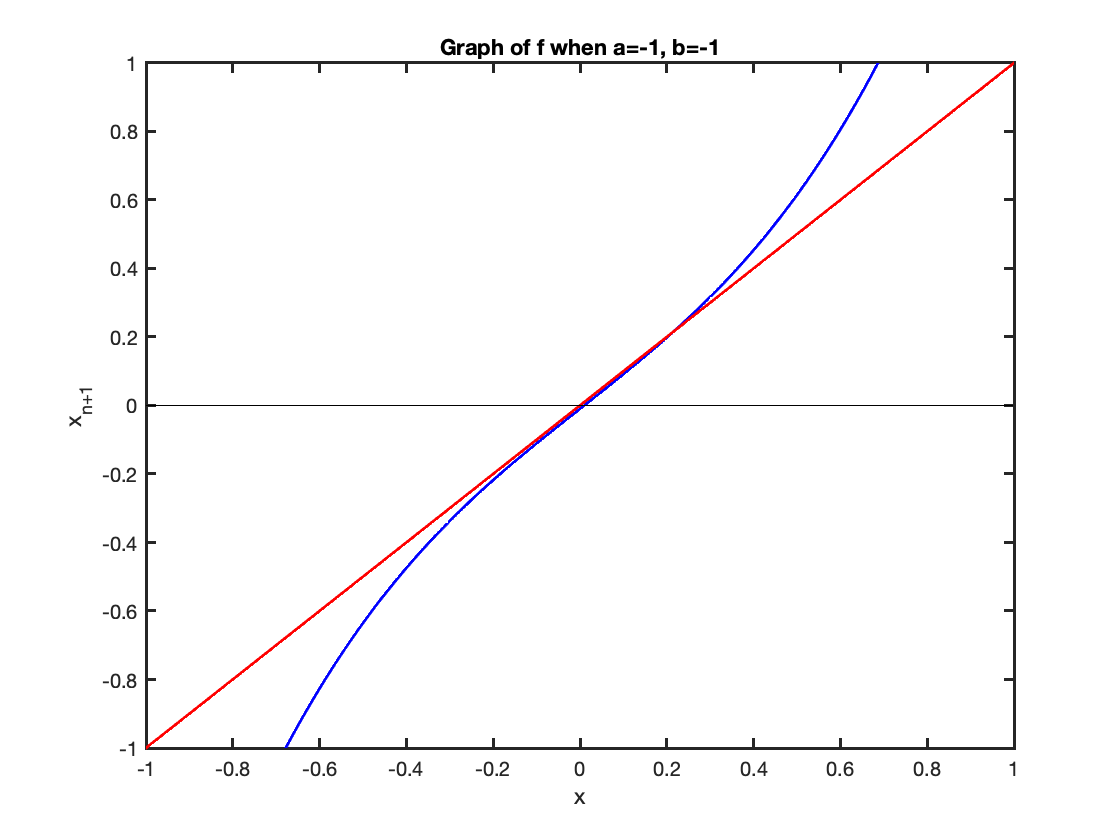

x=[-1:0.001:1];
y = x.^3 -(-1)*x - 0.01;
z=x;
w = x-x;
plot(x,y,'b','linewidth',1.5)
hold on
plot(x,z, 'r', 'linewidth',1.5)
plot(x, w, 'k', 'linewidth',0.5)
ylim([-1 1])
set(gcf,'color','w');
set(gca,'linewidth',1.5)
xlabel('x');
ylabel('x_{n+1}');
title('Graph of f when a=-1, b=-1');
hold off